Irene Celestino - Daniele Poidomani 

16/11/2021

# Logbook 

## Es. 1

Abbiamo costruito il circuito, usando come resistenza del Gain Rg=1 kOhm e come resistenza del Source Rs=10 Ohm. Abbiamo preso per Rs la resistenza più bassa possibile, perché le correnti che scorrono nel circuito devono essere sotto 10 mA. 

## Es. 2 - Tensione di Soglia del MOSFET

Abbiamo collegato l'amperometro per misurare la corrente che scorre nel transistor (messo tra l'analog output CB21 e il drain). 

Abbiamo impostato con Vin_Vout_2C.vi per prima cosa Vdrain a 0.1 V. Misurando Vdrain con il multimetro si ottiene $0.999 \pm$ V.

Abbiamo poi cambiato Vgate (CB22) e misurato la corrente con l'amperometro e Vs (CB33):

- $V_g = 0.999 \pm 0.007$ V : $I = 0$ A  - $V_s = 0$ V

- $V_g=1.498 \pm 0.007$ V:  $I = 0.06 \pm 0.02 \mu$A - $V_s = 0$ V

- $V_g= 1.717 \pm 0.007$ V : $I=1.0 \pm 0.1 \mu$A - $V_s = 0$ V

- $V_g =1.800 \pm 0.007$ V : $I=2.9 \pm 0.1 \mu$A - $V_s = 0$ V

- $V_g =1.898 \pm 0.006$ V : $I = 9.8 \pm 0.1 \mu$A - $V_s= 0.22 \pm 0.08$ mV

- $V_g = 1.998 \pm 0.007$ V : $I = 32.97 \pm 0.04\mu$A - $V_s= 0.49 \pm 0.06$ mV

- $V_g=2.995 \pm 0.007$ V : $I= 4.05\pm 0.05$ mA - $V_s= 45.74 \pm 0.14$ mV 

- $V_g=3.994 \pm 0.007$ V :  $I= 4.880 \pm 0.004$ mA - $V_s= 52.04 \pm 0.09$ mV

Si può quindi stimare che $V_T$ è intorno ai 2 V, in accordo con il valore tipico riportato dal datasheet, 2.1 V

## Es. 3 - Corrente del Gain

Abbiamo collegato l'amperometro il serie alla resistenza del Gain (tra Rg e CB22) e misurato la corrente che scorre in Rg, variando Vg con Vin_Vout_2C.vi

Viene sempre una corrente di 0 A: il valore massimo misurato è $1.00 \pm 0.06 \mu$A per Vg = 4 V. 

Avevamo verificato che non scorresse corrente anche nell'esercizio precedente: abbiamo messo CB68 tra la resistenza e il Gain e la tensione che si misura lì è sempre compatibile con quella impostata nel vi, quindi non c'è caduta di tensione ai capi di Rg.

## Es. 4 e 5 - Aggiunta dell'OpAmp

La corrente $I_{DS}$ non entra nell'ingresso invertente dell'OpAmp, ma scorre nella resistenza di feeedback e poi entra nell'OpAmp dall'uscita. Ci serve quindi un OpAmp con una resistenza di ingresso molto alta, o almeno molto maggiore di Rtran. 

Abbiamo usato uA741C, in modo da lavorare in un range ampio di tensioni, tra -12 e 12 V, nonostante abbia una resistenza di ingresso più bassa di altri modelli a nostra disposizione. 

Abbiamo scelto Rtrans = 100 Ohm, di vari ordini di grandezza inferiore a quella dell'OpAmp, dell'ordine di 0.3-2 MOhm. 

## Es. 6 - Corrente di Drain VS Tensione di Drain

Abbiamo usato FET_vs_DRAIN.vi per misurare la curva $I_{DS}$ VS $V_{DS}$ al variare di $V_{GS}$.

Impostazioni sul vi (mantenute uguali per tutte le misure con FET_vs_DRAIN.vi e con FET_vs_GAIN.vi): 

- n misure = 100

- Fondoscala = 10 V per Vgs, 0.5 oppure 5 V per gli altri

Abbiamo preso la prima misura con $V_{GS}$= 2.5 V, poco sopra la soglia, con $V_{DS}$ che variava prima tra 0 e 0.5 V, per concentrarci sulla zona lineare, e poi tra 0 e 1 V, per studiare anche la zona di saturazione. 

$I_{DS}$ **per **$V_{DS}$ **tra 0 e 1 V**

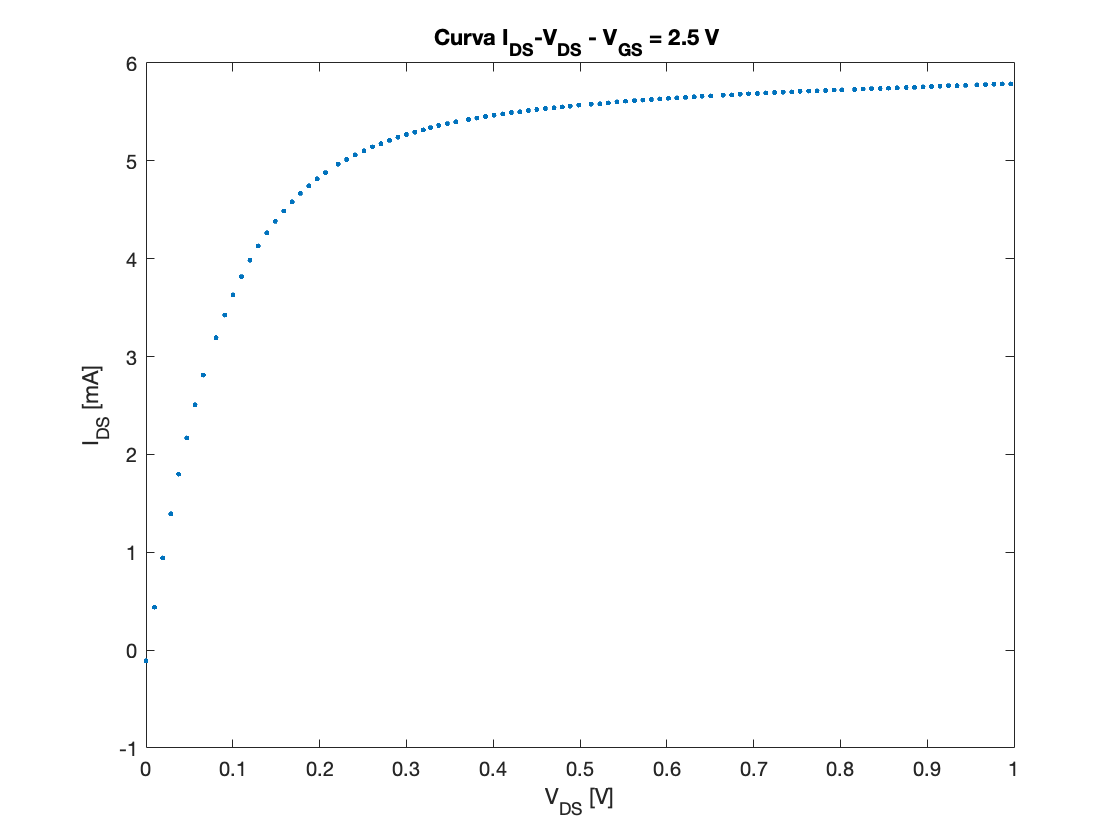

R=100;%ohm
dR=1;
datamat=readmatrix('Data LAB es 6 2');
Vd=datamat(:,1);
Id=datamat(:,2);
Vout=Id*R;
dig_V=2*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_V/R)^2+(Vout/R^2*dR).^2); %digitalizzazione

plot(Vd, Id,'.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.5 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

$I_{DS}$ **per **$V_{DS}$ **regime lineare**

datamat=readmatrix('Data LAB es 6');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:12);
Vd_fit=Vd(1:12);
Vout=Id_fit/R;

dig_Vout=20*2^(-12); %digitalizzazione
dig_V=1*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id_fit), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione

errorbar(Vd_fit, Id_fit*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.5 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId);
coefficiente=p(1)

coefficiente = 0.0474

dcoefficiente=dp(1)

dcoefficiente = 8.7147e-04

intercetta=p(2)

intercetta = -1.7869e-05

dintercetta=dp(2)

dintercetta = 2.6708e-05

chiqn

chiqn = 1.4305

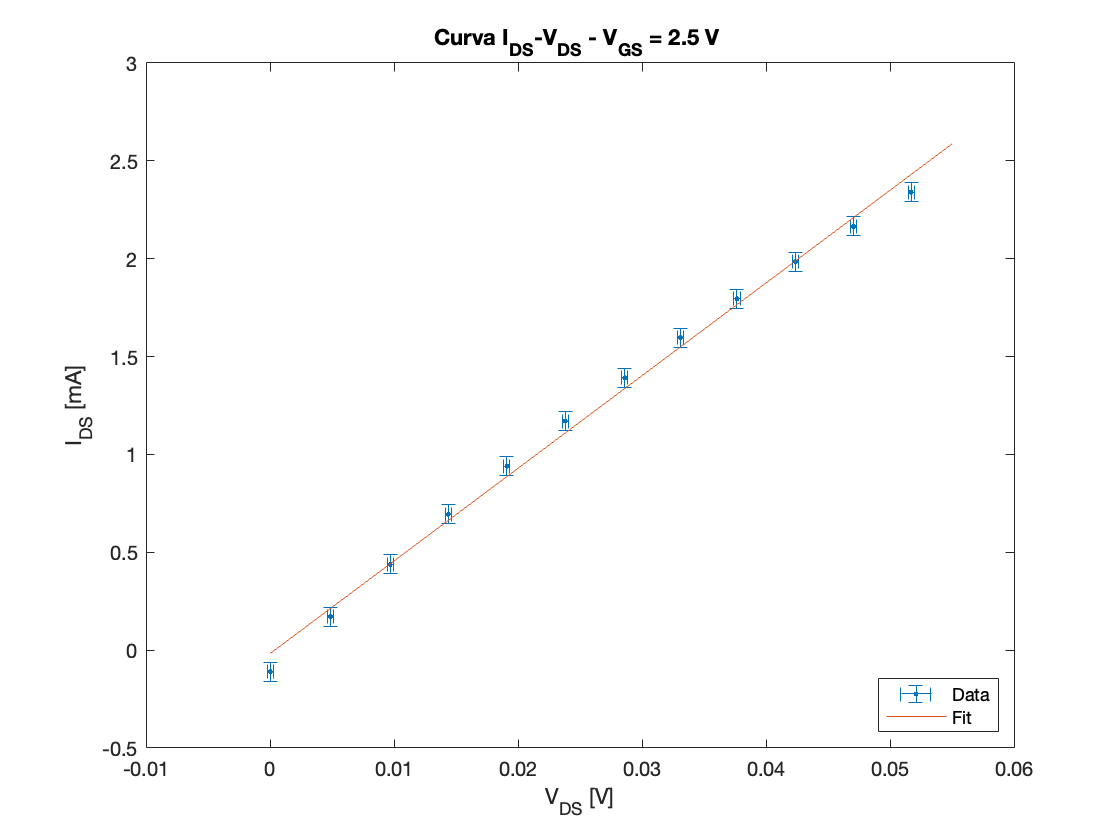

xx=linspace(0, 0.055, 100);
yy=p(1)*xx+p(2);

hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')


i=1;
Vg(i)=2.5;
coeff(i)=p(1);
dcoeff(i)=dp(1);
fine_lin(i)=max(Vd_fit);

Risultati del fit lineare: 

- coefficiente = $47.4 \pm 0.08$ mA/V

- intercetta = $-17 \pm 26$ $\mu$A (compatibile con 0)

- 
$$\chi^2_{norm} = 1.43$$


## Es. 7 - Corrente di Drain VS Tensione di Drain per diversi Vgs

Abbiamo poi ripetuto la stessa misura variando $V_{GS}$. Abbiamo preso valori di $V_{GS}$ piccoli (fino a 4 V), perché volevamo mantenere la corrente sotto i 10 mA, o comunque sotto i 20 mA. Per correnti superiori a questa, infatti, l'OpAmp smette di funzionare perché la sua *Short-circuit output current* vale 25 mA.

Abbiamo quindi impostato il range di $V_{DS$ per rimanere a correnti basse, anche se per $V_{GS}$ = 3 e 4 V siamo arrivati a 20 mA. 

Valori scelti di $V_{GS}$: 2.2, 2.3, 2.4, 2.6, 3, 4 V

$I_{DS}$ **vs **$V_{DS}$ **per **$V_{GS}$ **= 2.3 V**

R=100;%ohm
dR=1;
datamat=readmatrix('Data LAB es 7 vg 2,3');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:15);
Vd_fit=Vd(1:length(Id_fit));
Vout=Id/R;

dig_Vout=10*2^(-12); %digitalizzazione
dig_V=1*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:length(Id_fit));
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.3 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId_fit);
coefficiente=p(1)

coefficiente = 0.0124

dcoefficiente=dp(1)

dcoefficiente = 3.0032e-04

intercetta=p(2)

intercetta = 3.4001e-05

dintercetta=dp(2)

dintercetta = 1.2004e-05

chiqn

chiqn = 3.2940

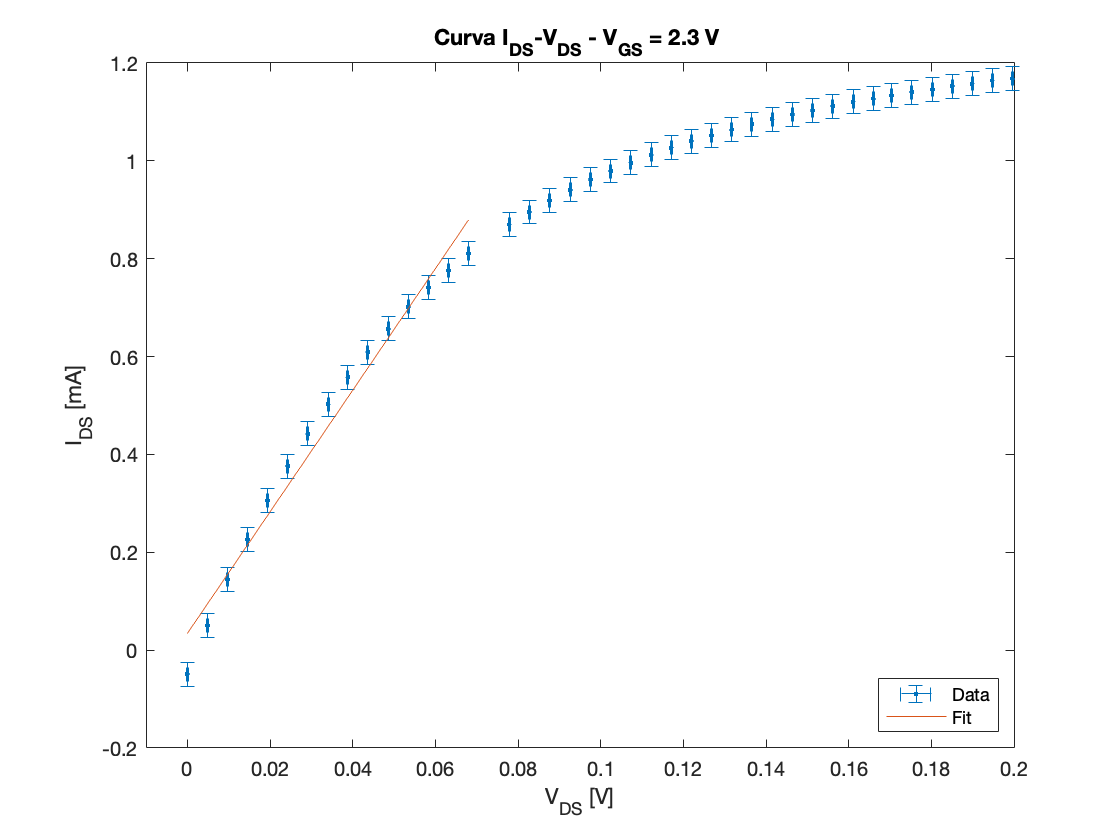

xx=linspace(0, max(Vd_fit), 100);
yy=p(1)*xx+p(2);
%ylim([-1,20.5])

xlim([-0.01, 0.2])

hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')


i=i+1;
Vg(i)=2.3;
coeff(i)=p(1);
dcoeff(i)=dp(1);
fine_lin(i)=max(Vd_fit);

Risultati del fit lineare: 

- coefficiente = $12.4 \pm 0.3$ mA/V

- intercetta = $34 \pm 12$ $\mu$A 

- 
$$\chi^2_{norm} = 3.2$$


Su questa provo anche modello completo, che vale per $V_{DS}<V_{GS}-V_T \simeq 0.2$ V: 


$$I_{DS} = - K_n V_T + K_n V_{GS} V_{DS} - \frac{K_n}{2} V_{DS}^2$$
 

Id_fit=Id(1:50);
Vd_fit=Vd(1:length(Id_fit));
Vout=Id/R;

dig_Vout=10*2^(-12); %digitalizzazione
dig_V=1*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:length(Id_fit));
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.3 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

pin=[-0.25*2.1, 0.25*2.3, -0.25/2]'

pin = 	1.0e+-3 *

   -0.5250
    0.5750
   -0.1250


modello = @(p,x)(p(1)+x*p(2)+x.^2*p(3));
[p,resnorm,JJ,COVB,chi2n]=nlinfit(Vd_fit, Id_fit,modello,pin,'Weights', dId_fit.^(-2));
parametri_fit=p;
p(1)

ans = 1.1049e-04

p(2)

ans = 0.0112

p(3)

ans = -0.0289

for i=1 : length(p)
err_parametri_fit(i)=sqrt(COVB(i,i));
end
err_parametri_fit

err_parametri_fit =     0.0000    0.0004    0.0016


chisq_norm=chi2n

chisq_norm = 5.0350

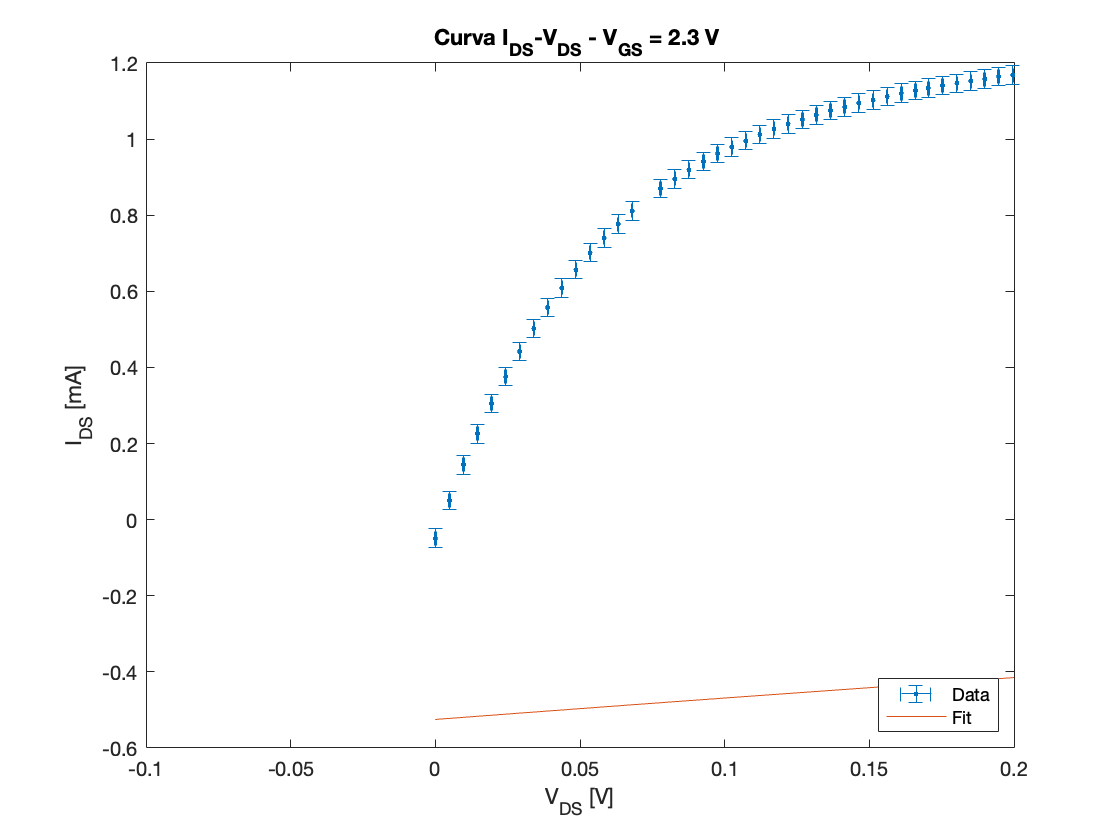

xx=linspace(0,max(Vd_fit), 1000);
yy=pin(1)+xx*pin(2)+xx.^2*pin(3);
hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')
xlim([-0.1, 0.2])

Fit fatto per $V_{DS}$ fino a 0.12 V. 

$I_{DS}$ **vs **$V_{DS}$ **per **$V_{GS}$ **= 2.4 V**

R=100;%ohm
dR=1;
datamat=readmatrix('Data LAB es 7 vg 2,4');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:15);
Vd_fit=Vd(1:length(Id_fit));
Vout=Id/R;

dig_Vout=20*2^(-12); %digitalizzazione
dig_V=2*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:length(Id_fit));
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.4 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId_fit);
coefficiente=p(1)

coefficiente = 0.0253

dcoefficiente=dp(1)

dcoefficiente = 6.0930e-04

intercetta=p(2)

intercetta = 4.8920e-05

dintercetta=dp(2)

dintercetta = 2.4077e-05

chiqn

chiqn = 2.0739

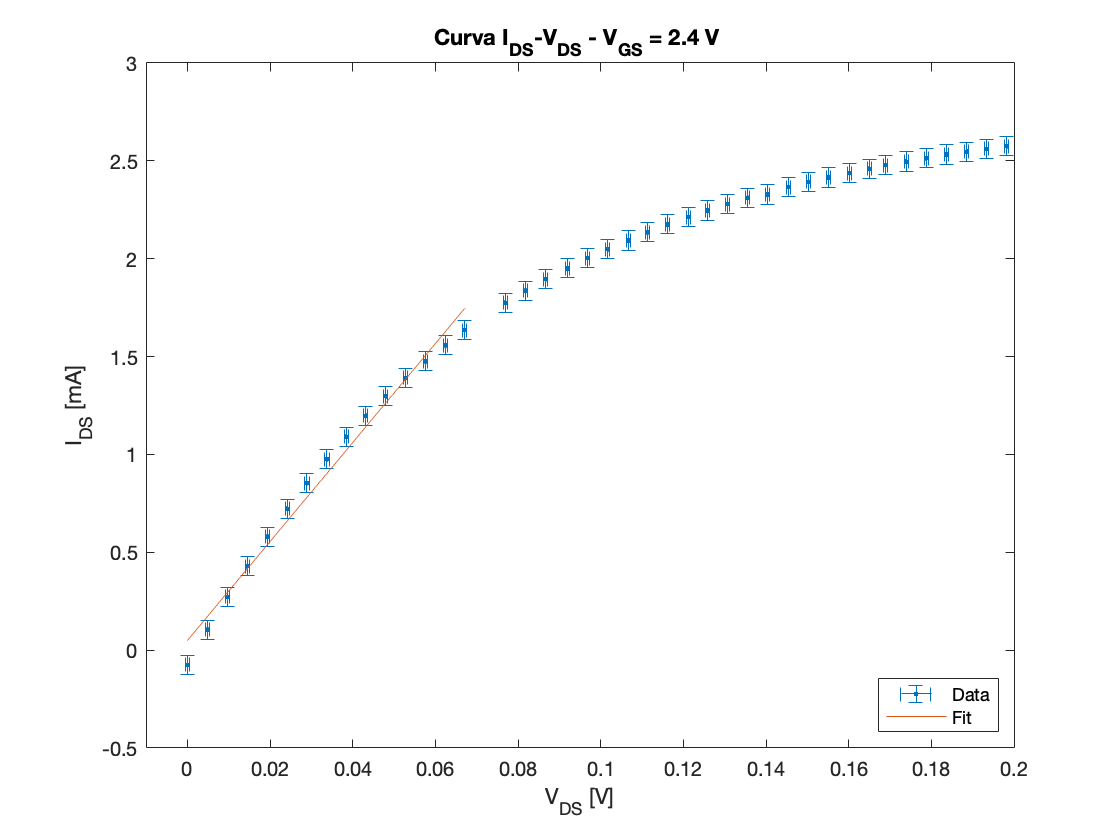

xx=linspace(0, max(Vd_fit), 100);
yy=p(1)*xx+p(2);
%ylim([-1,20.5])

xlim([-0.01, 0.2])

hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')


i=i+1;
Vg(i)=2.4;
coeff(i)=p(1);
dcoeff(i)=dp(1);
fine_lin(i)=max(Vd_fit);

Risultati del fit lineare: 

- coefficiente = $67.5 \pm 0.6$ mA/V

- intercetta = $46 \pm 24$ $\mu$A 

- 
$$\chi^2_{norm} = 6.2$$


$I_{DS}$ **vs **$V_{DS}$ **per **$V_{GS}$ **= 2.6 V**

R=100;%ohm
dR=1;
datamat=readmatrix('Data LAB es 7 vg 2,6');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:15);
Vd_fit=Vd(1:length(Id_fit));
Vout=Id/R;

dig_Vout=20*2^(-12); %digitalizzazione
dig_V=2*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:length(Id_fit));
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 2.6 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId_fit);
coefficiente=p(1)

coefficiente = 0.0675

dcoefficiente=dp(1)

dcoefficiente = 6.2578e-04

intercetta=p(2)

intercetta = 4.6127e-05

dintercetta=dp(2)

dintercetta = 2.4019e-05

chiqn

chiqn = 6.2456

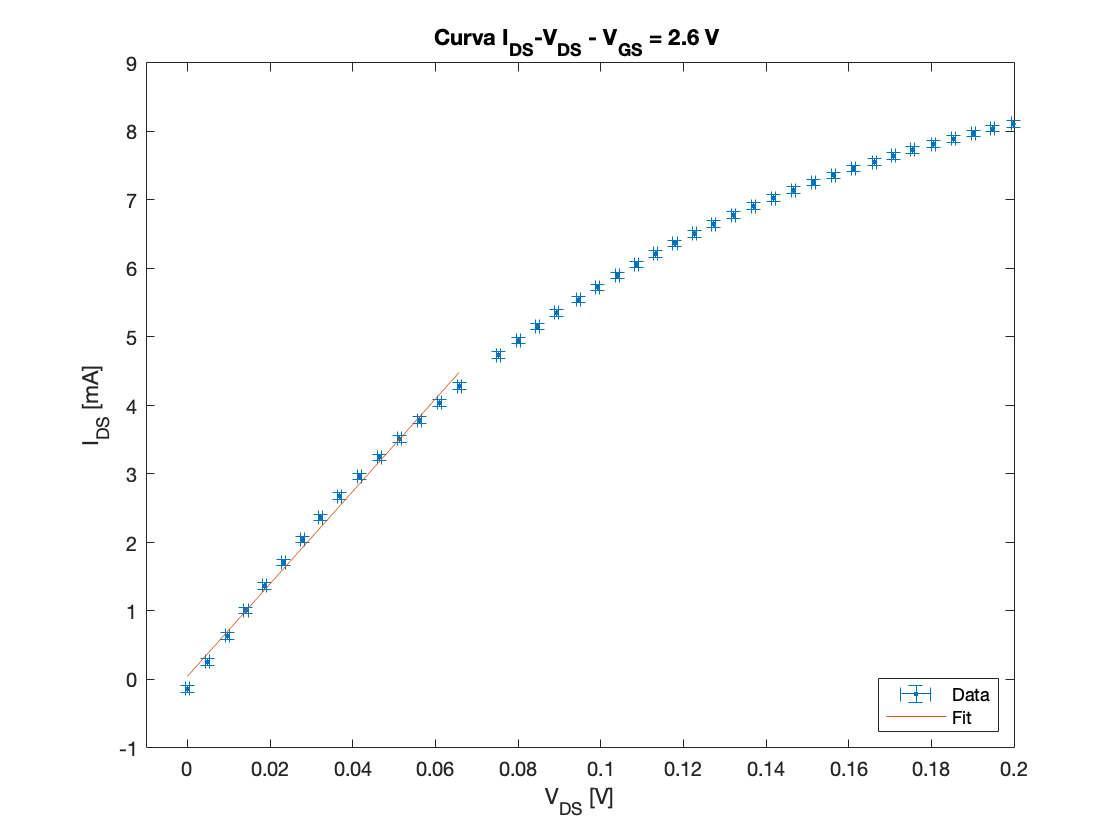

xx=linspace(0, max(Vd_fit), 100);
yy=p(1)*xx+p(2);
%ylim([-1,20.5])

xlim([-0.01, 0.2])

hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')


i=i+1;
Vg(i)=2.6;
coeff(i)=p(1);
dcoeff(i)=dp(1);
fine_lin(i)=max(Vd_fit);

Risultati del fit lineare: 

- coefficiente = $67.5 \pm 0.6$ mA/V

- intercetta = $46 \pm 24$ $\mu$A 

- 
$$\chi^2_{norm} = 6.2$$


$I_{DS}$ **vs **$V_{DS}$ **per **$V_{GS}$ **= 3 V**

R=100;%ohm
dR=1;
datamat=readmatrix('Data LAB es 7');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:80);
Vd_fit=Vd(1:80);
Vout=Id/R;

dig_Vout=20*2^(-12); %digitalizzazione
dig_V=2*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:80);
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 3 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId_fit);
coefficiente=p(1)

coefficiente = 0.1765

dcoefficiente=dp(1)

dcoefficiente = 1.7383e-04

intercetta=p(2)

intercetta = 1.9845e-04

dintercetta=dp(2)

dintercetta = 1.0765e-05

chiqn

chiqn = 33.9379

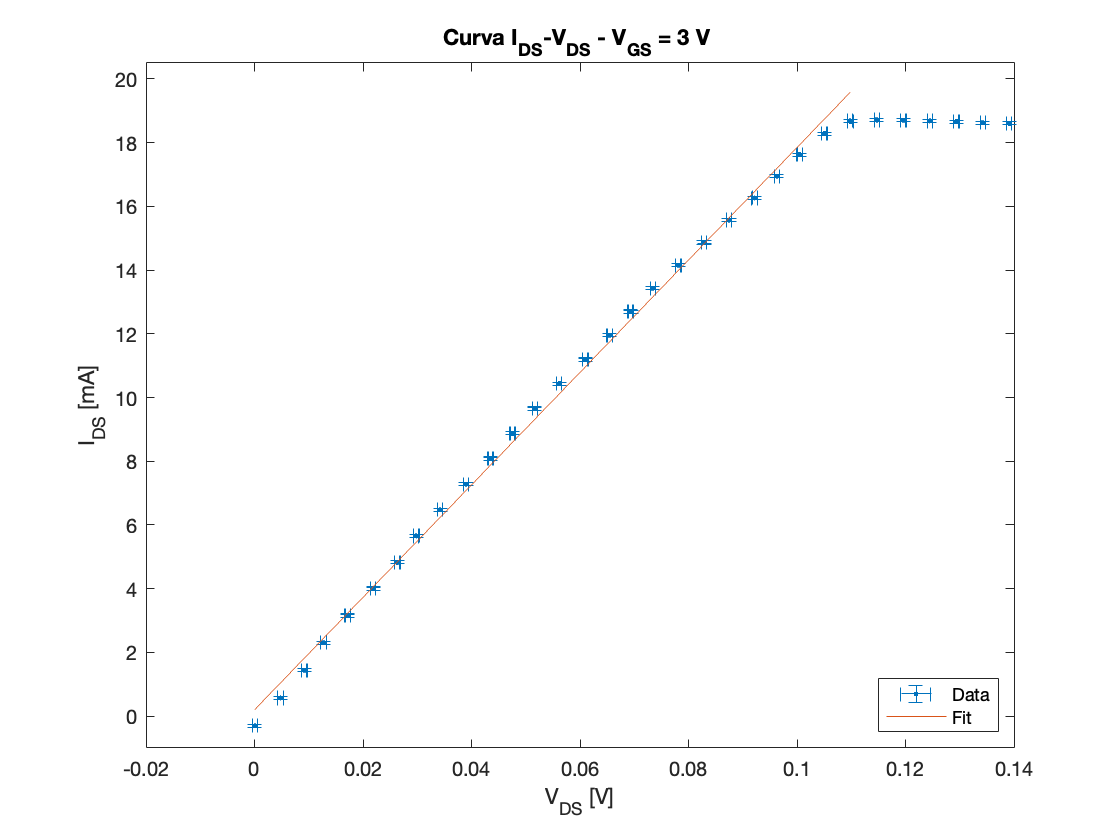

xx=linspace(0, max(Vd_fit), 100);
yy=p(1)*xx+p(2);
ylim([-1,20.5])

hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')


i=i+1;
Vg(i)=3;
coeff(i)=p(1);
dcoeff(i)=dp(1);
fine_lin(i)=max(Vd_fit);

Risultati del fit lineare: 

- coefficiente = $176.5 \pm 0.2$ mA/V

- intercetta = $0.20 \pm 0.01$ mA 

- 
$$\chi^2_{norm} = 33.9$$


$I_{DS}$ **vs **$V_{DS}$ **per **$V_{GS}$ **= 4 V**

R=100;%ohm
dR=1;
datamat=readmatrix('Data LAB es 7 vg 4');
Vd=datamat(:,1);
Id=datamat(:,2)*1e-3; %in A, misure in mA

Id_fit=Id(1:33);
Vd_fit=Vd(1:length(Id_fit));
Vout=Id/R;

dig_Vout=20*2^(-12); %digitalizzazione
dig_V=2*2^(-12); %digitalizzazione
dVd=dig_V*ones(length(Id), 1);
dId=sqrt((dig_Vout/R)^2+(Vout*dR/R^2).^2); %digitalizzazione
dId_fit=dId(1:length(Id_fit));
errorbar(Vd, Id*1e3, dId*1e3, dId*1e3, dVd, dVd, '.')
title('Curva I_{DS}-V_{DS} - V_{GS} = 4 V ')
ylabel('I_{DS} [mA]')
xlabel('V_{DS} [V]')

%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vd_fit, Id_fit, dId_fit);
coefficiente=p(1)

coefficiente = 0.3773

dcoefficiente=dp(1)

dcoefficiente = 5.5277e-04

intercetta=p(2)

intercetta = -5.8803e-04

dintercetta=dp(2)

dintercetta = 1.6676e-05

chiqn

chiqn = 5.9353

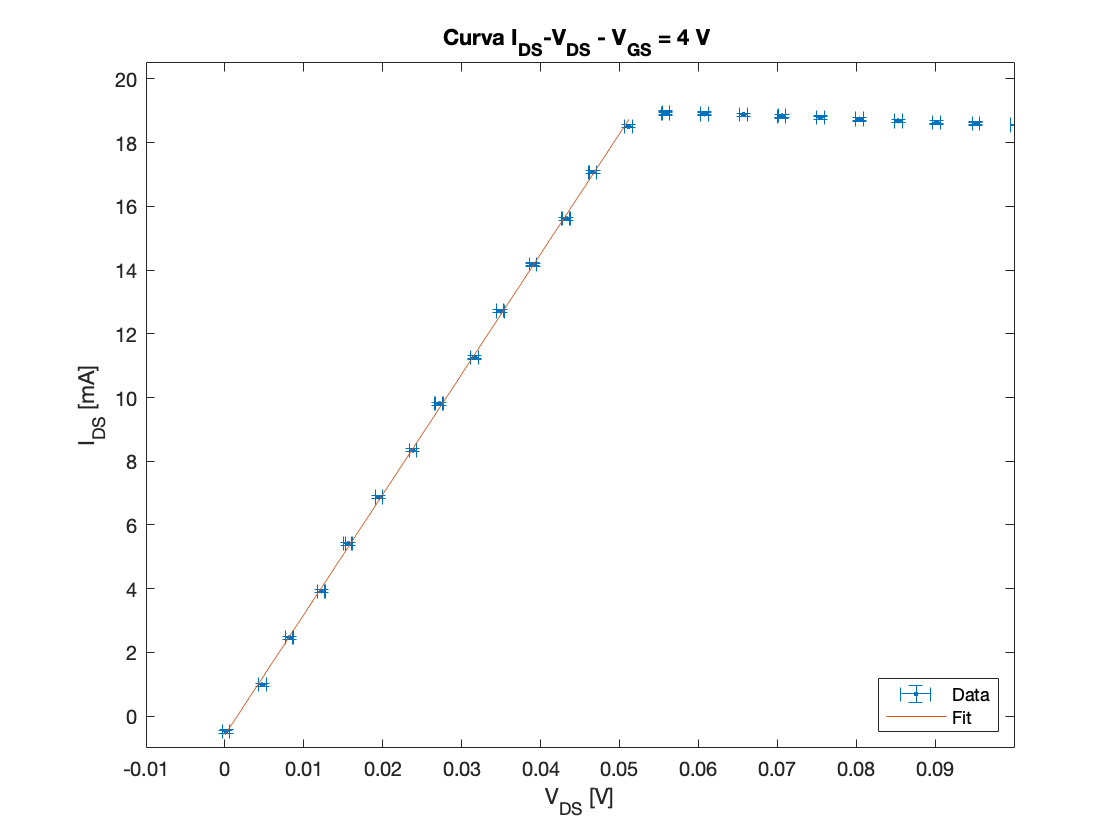

xx=linspace(0, max(Vd_fit), 100);
yy=p(1)*xx+p(2);
ylim([-1,20.5])

xlim([-0.01, 0.1])

hold on 
plot(xx,yy*1e3)
hold off
legend('Data', 'Fit', 'Location','southeast')



i=i+1;
Vg(i)=4;
coeff(i)=p(1);
dcoeff(i)=dp(1);
fine_lin(i)=max(Vd_fit);

Risultati del fit lineare: 

- coefficiente = $377.3 \pm 0.6$ mA/V

- intercetta = $-0.59 \pm 0.02$ mA 

- 
$$\chi^2_{norm} = 5.9$$


Qui si ferma a 20 mA perché OpAmp non può lavorare a correnti maggiori: non ha senso vedere lunghezza zona lineare qui. 

**Studio del coefficiente **$I_{DS}/V_{DS}$ **al variare di **$V_{GS}$

Il valore atteso per il coefficiente $I_{DS}/V_{DS}$, se $V_{DS} \ll V_{GS}-V_T$, è dato da :

$K_n (V_{GS}-V_T)$, con $K_n = 0.25$ mA/V$^2$. 

Fit lineare di $I_{DS}/V_{DS}$ VS $V_{GS}$:

errorbar(Vg, coeff, dcoeff, dcoeff, '.')
%fit
[p, dp, chiqn, prod, corr]= fitpoli(1,Vg, coeff, dcoeff);
coefficiente=p(1)

coefficiente = 0.2253

dcoefficiente=dp(1)

dcoefficiente = 3.1904e-04

intercetta=p(2)

intercetta = -0.5049

dintercetta=dp(2)

dintercetta = 9.1393e-04

Vt=-intercetta/coefficiente

Vt = 2.2407

dVt=sqrt((dintercetta/coefficiente)^2+(intercetta/coefficiente^2*dcoefficiente)^2)

dVt = 0.0051

chiqn

chiqn = 681.3575

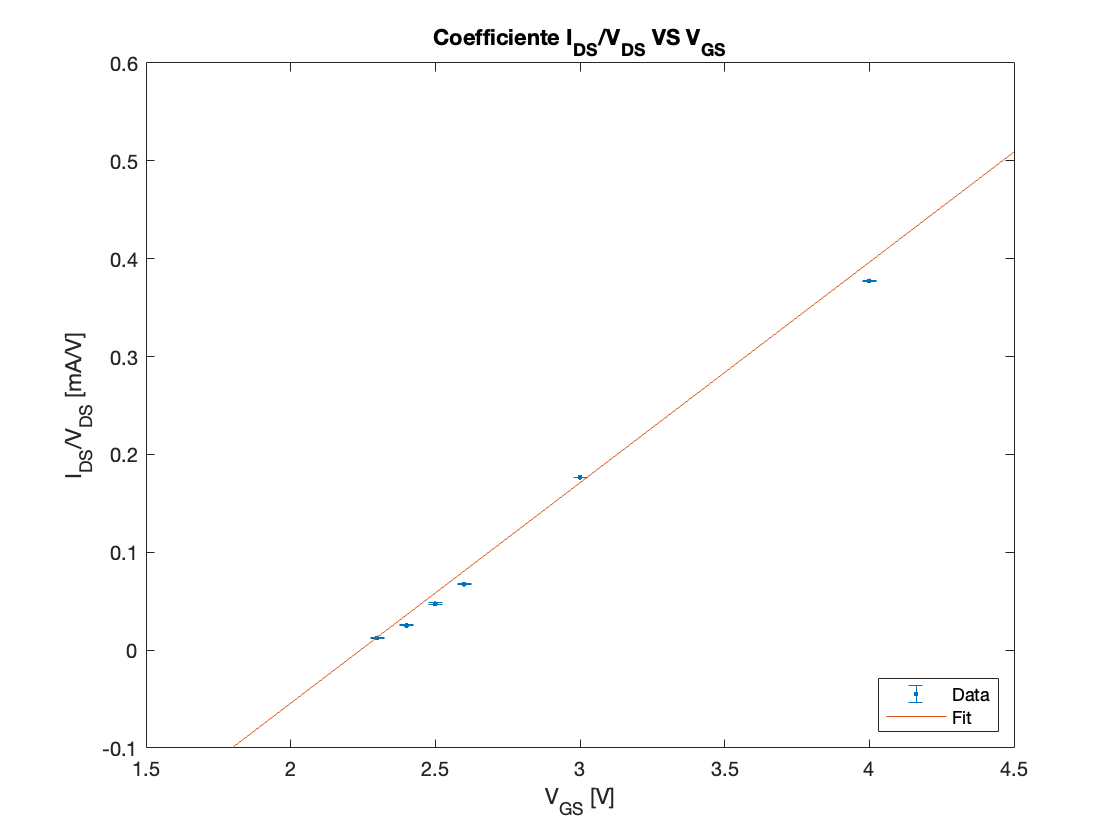

xx=linspace(min(Vg)-0.5, max(Vg)+0.5, 100);
yy=p(1)*xx+p(2);

hold on 
plot(xx,yy)
hold off
legend('Data', 'Fit', 'Location','southeast')
title('Coefficiente I_{DS}/V_{DS} VS V_{GS}')
xlabel('V_{GS} [V]')
ylabel('I_{DS}/V_{DS} [mA/V]')

Risultati del fit lineare: 

- $K_n$ = $0.2239 \pm 0.0003$ mA/V$^2$

- intercetta = $-K_n V_T$= $-0.5004 \pm 0.0009$ mA/V 

- $V_T = 2.235 \pm 0.005$ V

- 
$$\chi^2_{norm} = 767$$


Errori su $I_{DS}/V_{DS}$ sono sottostimati perché il chi quadro normalizzato viene grande.

## Es. 8 

Montato con Rtrans = 100 Ohm 

Inizio (sbagliato)

Decidiamo Vdrain= 0.08 (regime lineare, ma non troppo alto per avere I sotto 10 mA e Vg non basso) 

Abbiamo inizialmente fatto variare Vgate a partire da 1,5 V ed è costantemente 0 fino a Vg = 2 V. Per questo motivo, scegliamo intervallo Vgate a partire da 2 e fino alla Vg per cui si rimane sotto i 10 mA per corrente Ids

Vg tra 2 e 2.9 V 

Ora ci mettiamo in saturazione (V drain 1 V)  - Vg tra 2 e 2.6 V 

## Es. 9 

Regime lineare

1) Vdrain 0.1 e 2.2.6 V 

2) 2-2.7 V con Vd 0.09V 

Regime saturazione: 

1) Vd = 3.3 V e Vg tra 2 e 2.5V 

2) Vd = 4 V e Vg tra 2 e 2.5 V 

## Es. 11

Prima misura: V

Con Op37 abbiamo usato R=150 Ohm 

La seconda misura è con sempre OP, un altro OpAmp però 

## Es. 13

Nell'ATTENZIONE : cambiare valore finale di Vgs 

Andare in FET_vs_DRAIN.vi: alla fine nel 9 modifica il valore di CB22 (ao0) a 0: modificare quella costante da 0 al valore desiderato 

Poi nel primo frame (0) cambiare l'intervallo massimo da 5 a 10, così si può andare negativi 

Modificato e creato nuovo vi: JFET_vs_DRAIN 

**Partiamo da curva Id-Vds**

Vogliamo rimanere sempre sotto 10 mA

Soglia è tra -7  (I sempre 0) e -6.5 V (fa retta)

Misura 1: Vg= -6.5 e Vd tra 0 e 2.4 V (misura 13-6)

Misura 2: Vg = -6.4, Vd tra 0 e 1.5 (misura 13-7)

**Curva Id-Vgs**

Misura 1: Vd=3.3 V e Vg tra -7 e -6.5  (misura 13-8)

Misura 2: Vd=2 V e Vg tra -7 e -6.4 (misura 13-9 )

**Curva Id-Vgs con generatore **

Mettiamo Vd = 2.5 (Misura Vdrain = 2.53 V) e Vg tra -7 e -6.35 

Misura 13-11

# Sezione Risultati

## Es. 2 - Tensione di Soglia del MOSFET

$V_T$ è intorno ai 2 V, in accordo con il valore tipico riportato dal datasheet, 2.1 V